#  Initialization

clear
close all
clc

# Parameters

This Project focus on Fixed Pilot Length.

M       = 128;                      % Num of Antenna in BS
Ma      = 32;                       % Num of Selected Antenna
Mb      = M - Ma;                   % Num of Channel that should be Estimated
K       = 20;                       % Num of Users
L       = 10;                       % Num of MultiPath
N       = 50000;                    % Num of Realization
T_ch    = 200;                      % Coherence interval
SNR_dB  = (10:10:30);               % SNR in dB
SNR     = 10.^((-1)*(SNR_dB/10));   % SNR - Real Value
Eps     = 0.001;                    % Epsilon
Ant_Set = 1:M;                      % Antenna Set
T       = [40 48 64 80 96 128];     % Lenght of Pilot Sequence

# Main Body

Different Pilot Length

SNR : 10   Tau : 40


SNR : 10   Tau : 48


SNR : 10   Tau : 64


SNR : 10   Tau : 80


SNR : 10   Tau : 96


SNR : 10   Tau : 128


SNR : 20   Tau : 40


SNR : 20   Tau : 48


SNR : 20   Tau : 64


SNR : 20   Tau : 80


SNR : 20   Tau : 96


SNR : 20   Tau : 128


SNR : 30   Tau : 40


SNR : 30   Tau : 48


SNR : 30   Tau : 64


SNR : 30   Tau : 80


SNR : 30   Tau : 96


SNR : 30   Tau : 128


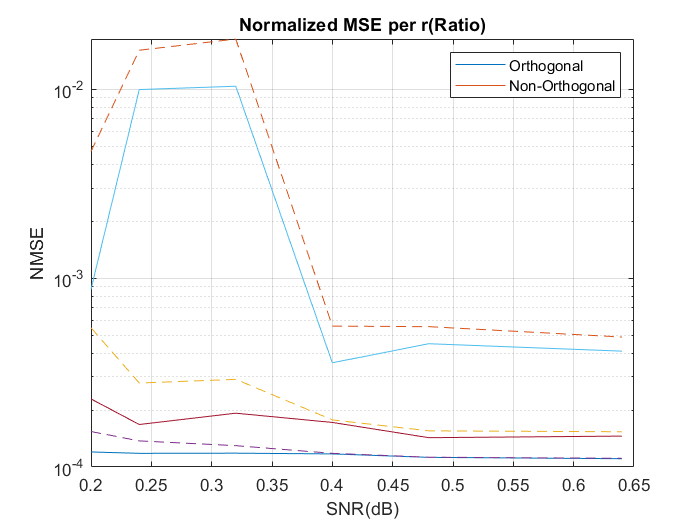

tic

% O  ~> Orthogonal Pilot Sequence
% No ~> Non-Orthogonal Pilot Sequence

NMSE_Tot_O  = zeros(length(SNR),length(T));
NMSE_Tot_No = zeros(length(SNR),length(T));

for s=1:length(SNR)
    
    
    
    for t=1:length(T)
        
        disp(['SNR : ',num2str(SNR_dB(s)),'   Tau : ',num2str(T(t))])
        disp(' ')
        
        NMSE_O  = zeros(1,N);
        NMSE_No = zeros(1,N);
        
        for n=1:N
            
            % ---------------------------
            %       First Initialize
            Y_O      = zeros(1,T(t),K);
            Y_No     = zeros(1,T(t),K);
            % ---------------------------
            H_O      = zeros(1,Ma,K);
            H_No     = zeros(1,Ma,K);
            % ---------------------------
            HI_O     = zeros(L,Ma + 1,K);
            HI_No    = zeros(L,Ma + 1,K);
            % ---------------------------
            Ki_O     = zeros(Ma + 1,Mb,K);
            Ki_No    = zeros(Ma + 1,Mb,K);
            % ---------------------------
            h_b_O    = zeros(1,Mb,K);
            h_b_No   = zeros(1,Mb,K);
            % ---------------------------
            PiCh_O   = zeros(1,T(t),K);
            PiCh_No  = zeros(1,T(t),K);
            % ---------------------------
            H_O_hat  = zeros(1,Ma,K);
            H_No_hat = zeros(1,Ma,K);
            % ---------------------------
            Error_O  = zeros(1,K);
            Error_No = zeros(1,K);
            % ---------------------------
            % ---------------------------
            Dist           = 9 * rand(1,K);                         % Distance of Users from BS
            [Set_A,Set_B]  = Set_a(Ant_Set,M,Ma);                   % Selected Antenna
            [Ch,Ch_A,Ch_B] = Rayleigh(L,K,M,Ma,Set_A,Set_B,Dist);   % Total & Selected Channel
            
            P_O     = Pilot(Ma,T(t),K);                             % Orthogonal Pilot Sequence
            P_No    = (2*randi([0 1],Ma,T(t),K) - 1);               % Non Orthogonal Pilot Sequence
            
            P_OH    = Hermit(P_O,K);                                % Pilot Hermitian
            P_No_H  = Hermit(P_No,K);
            
            for k=1:K
                
                % Output of Channel
                PiCh_O(1,:,k)  = Ch_A(1,:,k) * P_O(:,:,k);
                PiCh_No(1,:,k) = Ch_A(1,:,k) * P_No(:,:,k);
                
                % Add Noise & Receiver Input
                Noise_O  = sqrt(SNR(s)) * randn(1,T(t));
                Noise_No = sqrt(SNR(s)) * randn(1,T(t));
                
                Y_O(1,:,k)  = PiCh_O(1,:,k)  + Noise_O;
                Y_No(1,:,k) = PiCh_No(1,:,k) + Noise_No;
                
                % Downlink Estimation of Orthogonal & Non_Orthogonal Pilot
                H_O(1,:,k)   = (Y_O(1,:,k)*P_OH(:,:,k))    / T(t);
                H_No(1,:,k)  = (Y_No(1,:,k)*P_No_H(:,:,k)) / (P_No(:,:,k)*P_No_H(:,:,k));
                
                % FeedBack CSI by adding a Random Value "delta"
                % Var(delta) = sqrt(epsilon)*Var(H_check_A)
                Del_O  = (sqrt(Eps)*var(H_O(1,:,k)))  * randn(1,Ma,K);
                Del_No = (sqrt(Eps)*var(H_No(1,:,k))) * randn(1,Ma,K);
                
                H_O_hat(1,:,k)  = H_O(1,:,k)  + Del_O(:,:,k);
                H_No_hat(1,:,k) = H_No(1,:,k) + Del_No(:,:,k);
                
                % HI   = [Re(Ch_A),1]
                HI_O(:,:,k)   = [Ch_A(:,:,k),ones(L,1)];
                HI_No(:,:,k)  = [Ch_A(:,:,k),ones(L,1)];
                
                % Regression Coefficient
                Ki_O(:,:,k)   = pinv(transpose(HI_O(:,:,k))  * HI_O(:,:,k))  * transpose(HI_O(:,:,k))*Ch_B(:,:,k);
                Ki_No(:,:,k)  = pinv(transpose(HI_No(:,:,k)) * HI_No(:,:,k)) * transpose(HI_No(:,:,k))*Ch_B(:,:,k);
                
                % Estimated Channel
                h_b_O(:,:,k)  = [H_O(1,:,k),1]*Ki_O(:,:,k);
                h_b_No(:,:,k) = [H_No(1,:,k),1]*Ki_No(:,:,k);
            end
            
            % Combination Estimated and FeedBack Channel
            H_Es_O  = ChCombine(H_O_hat,h_b_O,M,K,Set_A,Set_B);     % Estimated for Orthogonal Mode
            H_Es_No = ChCombine(H_No_hat,h_b_No,M,K,Set_A,Set_B);   % Estimated for Non-Orthogonal Mode
            Ch_Real = Ch(1,:,:);                                    % Real Values of Channel
            
            % Error Between Real Value & Estimated
            % Error = E{norm2(H - hat{H})^2 / norm2(H)^2}
            % H      : Real Channel (as a Target)
            % hat{H} : Estimated Channel
            for i=1:K
                Error_O(i)  = (norm(Ch_Real(1,:,i) - H_Es_O(1,:,i)))^2  / (norm(Ch_Real(1,:,i))^2);    % Orthogonal Error
                Error_No(i) = (norm(Ch_Real(1,:,i) - H_Es_No(1,:,i)))^2 / (norm(Ch_Real(1,:,i))^2);   % Non_Orthogonal Error
            end
            
            % NMSE on Num of Users
            NMSE_O(n)  = sum(Error_O)/K;
            NMSE_No(n) = sum(Error_No)/K;
        end                                 % End of for on Itterations
        
        % NMSE on Different SNRs
        NMSE_Tot_O(s,t)  = sum(NMSE_O) /N;
        NMSE_Tot_No(s,t) = sum(NMSE_No)/N;
    end
    
    
    %     figure(1)
    semilogy((T/T_ch),NMSE_Tot_O,...
        (T/T_ch),NMSE_Tot_No,'--')
    grid on
    hold on
    legend('Orthogonal','Non-Orthogonal')
    xlabel('SNR(dB)')
    ylabel('NMSE')
    title('Normalized MSE per r(Ratio)')
    
end                                     % End of for on SNRs




toc

Elapsed time is 83.096248 seconds.
